addpath Utility

%Format Scans pre-processes the data
FormatScans;

% We need to provide a guess as to where the lines are for line center
% fitting
site = 1;
if site == 1
    % Site I Guesses
    measured_lines = [
        %8763.51992; %Missing
        8766.012; %8765.97909;
        8767.435; %8767.40975;
        8769.91220;
        8770.32550;
        8770.51124
        8771.78475;
        8772.82845;
        8774.28335;
        8774.45087;
        8777.335; %8777.37150;
        8778.765; %8778.81256;
        ];

    widths = 0.15;
    num_curves = 6;
    
elseif site == 2

    %Site II Guesses
    measured_lines = [
        8768.12;
        8768.4;
        8769.92;
        8770.38;
        8770.68;
        8771.38;
        8771.66;
        8771.91;
        8772.19;
        8773.17;
        8774.16;
        ];

    widths = 0.4;
    num_curves = 5;
end

measured_lines = measured_lines';

%Get Rough Positions and Amplitudes of m_J lines
ExtractPositions(measured_lines, widths, num_curves);

if site == 2
    load(fullfile("Saves","coarse_lines.mat"));
    ExtractPositions(line_positions, 0.49*min(abs(diff(line_positions))), 1);
end

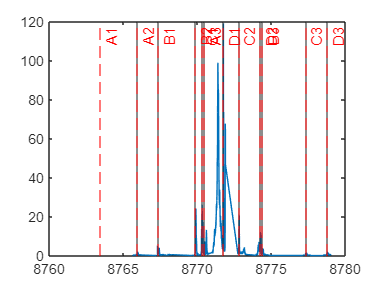

%Using the Fitted Positions, find the best level spacing
load(fullfile("Saves","coarse_lines.mat"));
LevelFitting(line_positions, line_positions_err);

clear;

%Fit the levels to a crystal field using brute force
%To use different CF operators, modify the CFFitting file
CFFitting;

Choosing 50 out of 100 points
Choosing 50 out of 100 points
Choosing 50 out of 100 points
Choosing 50 out of 100 points
Choosing 50 out of 100 points
Choosing 50 out of 100 points


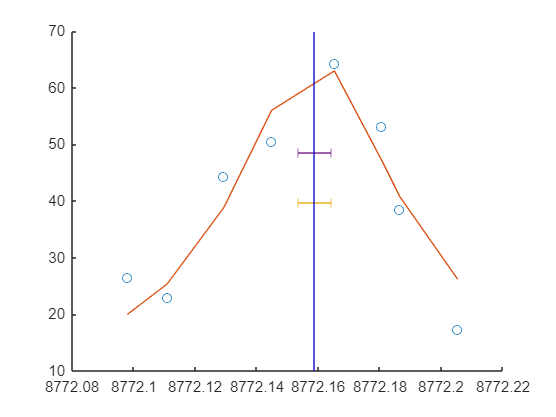


%Can also be done with fminsearch
CFFitting_J;

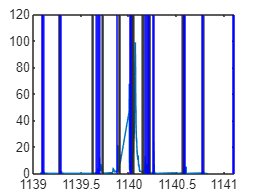

%Add hyperfine interactions to get the full hamiltonian
HFCoupling;


Local minimum possible.

lsqnonlin stopped because the final change in the sum of squares relative to 
its initial value is less than the value of the function tolerance.

<stopping criteria details>


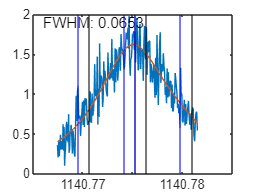


Local minimum possible.

lsqnonlin stopped because the final change in the sum of squares relative to 
its initial value is less than the value of the function tolerance.

<stopping criteria details>


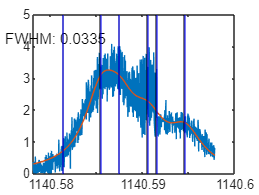


Local minimum possible.

lsqnonlin stopped because the final change in the sum of squares relative to 
its initial value is less than the value of the function tolerance.

<stopping criteria details>


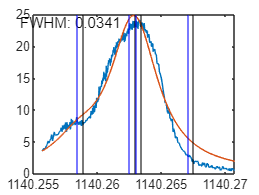


Local minimum possible.

lsqnonlin stopped because the final change in the sum of squares relative to 
its initial value is less than the value of the function tolerance.

<stopping criteria details>


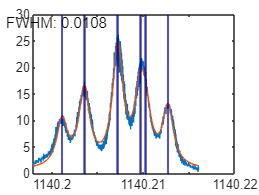


Local minimum possible.

lsqnonlin stopped because the final change in the sum of squares relative to 
its initial value is less than the value of the function tolerance.

<stopping criteria details>


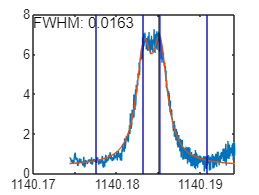


Local minimum possible.

lsqnonlin stopped because the final change in the sum of squares relative to 
its initial value is less than the value of the function tolerance.

<stopping criteria details>


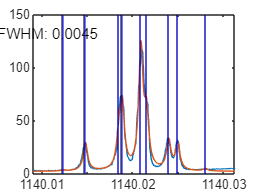


Local minimum possible.

lsqnonlin stopped because the final change in the sum of squares relative to 
its initial value is less than the value of the function tolerance.

<stopping criteria details>


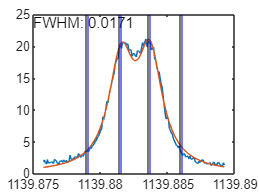


Local minimum possible.

lsqnonlin stopped because the final change in the sum of squares relative to 
its initial value is less than the value of the function tolerance.

<stopping criteria details>


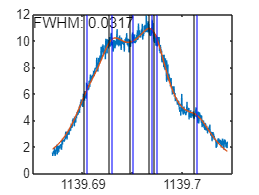


Local minimum possible.

lsqnonlin stopped because the final change in the sum of squares relative to 
its initial value is less than the value of the function tolerance.

<stopping criteria details>


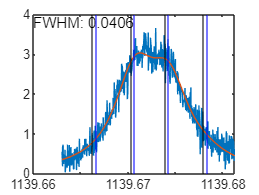


Local minimum possible.

lsqnonlin stopped because the final change in the sum of squares relative to 
its initial value is less than the value of the function tolerance.

<stopping criteria details>


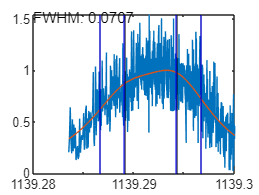


Local minimum possible.

lsqnonlin stopped because the final change in the sum of squares relative to 
its initial value is less than the value of the function tolerance.

<stopping criteria details>


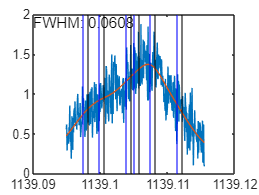

%If the resolution is available, we can now fit to more precisely to the
%hyperfine splitting
ExtractAmplitudes;

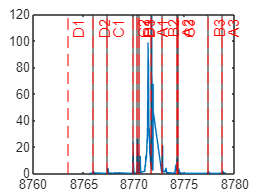

clear;
load(fullfile("Saves", "HFampfitting.mat"));

%Use the new fittings to get more accurate level fitting
load(fullfile("Saves","coarse_levels.mat"));
save(fullfile("Saves","old_coarse_levels.mat"), "gE", "eE", "gE_err", "eE_err");
load(fullfile("Saves","HFampfitting.mat"));
line_positions = [];
line_position_errs = [];
for i = 1:4:9
    for j = 1:4:13
        if i ~= 1 || j ~= 13
            line_positions(end+1) = mean(mean(amp_fitted_positions(i:(i+3),j:(j+3))));
            line_position_errs(end+1) = amp_fitted_position_errs(i,j);
        end
    end
end
%Limit by wavemeter error
line_position_errs = sqrt(line_position_errs.^2 + 0.002^2);
LevelFitting(line_positions, line_position_errs);

Choosing 50 out of 100 points
Choosing 50 out of 100 points
Choosing 50 out of 100 points
Choosing 50 out of 100 points
Choosing 50 out of 100 points
Choosing 50 out of 100 points


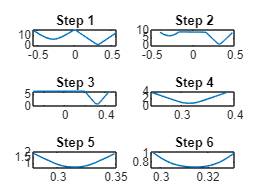

%Quick
CFFitting;

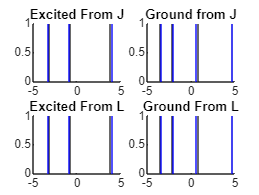

CFFitting_J;

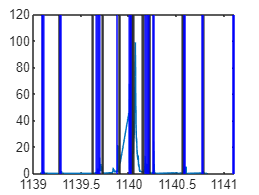

HFCoupling;


Local minimum possible.

lsqnonlin stopped because the final change in the sum of squares relative to 
its initial value is less than the value of the function tolerance.

<stopping criteria details>

Local minimum possible.

lsqnonlin stopped because the final change in the sum of squares relative to 
its initial value is less than the value of the function tolerance.

<stopping criteria d

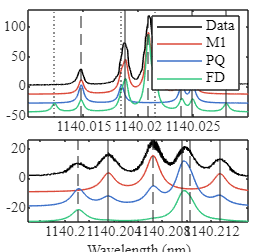

%Create the forced dipole and pseudoquadrupole transitions
ForcedDipoleTransition;
PseudoQuadTransition;

%Hacky
cd Fig2\
PlotAmplitudeFitting;

cd ..

%Now we can get any spectrum at any field strength
Bfield = 0;
linewidth = 0; %Use fitted linewidths
type = "unpolarized1";
sourcefile ="fittedPQ.mat";
%Keep M and E transitions at their original weights
Mweight = 1;
Eweight = 1;

figure;
load(fullfile("Saves","rough_position_scan.mat"));
plot(scan_wvs, scan);
hold on
[xaxis, scan] = FullInteraction(Bfield, linewidth, type, sourcefile, Mweight, Eweight);
plot(1e7./xaxis, scan);
[xaxis, scan] = FullInteraction(0.01, linewidth, type, sourcefile, Mweight, Eweight);
plot(1e7./xaxis, scan);
hold off